## **Pendolo smorzato**

Per verificare i risultati ottenuti analiticamente sfruttiamo il pacchetto Symbolic Toolbox di MATLAB, andiamo a definire i parametri simbolici dei quali avremo bisogno:

syms m l g theta(t) b;

Fatto ciò possiamo trattare questi elementi come se fossero dei parametri, in particolare l'ultimo "theta(t)" è una funzione, che contiene la dipendenza dalla variabile "t". Scriviamo ora l'energia **cinetica** e **potenziale**, e infine calcoliamo la Lagrangiana:

T = 1/2*m*l^2*diff(theta(t),t)^2

$$T = \frac{l^{2}\,m\,{\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}}{2}$$


V = -m*g*l*(cos(theta(t)))

$$V = -g\,l\,m\,\cos\left(\theta \left(t\right)\right)$$


L = T-V

$$L = \frac{m\,l^{2}\,{\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}}{2}+g\,m\,\cos\left(\theta \left(t\right)\right)\,l$$

Andiamo ora a svolgere i calcoli per scrivere l'equazione di Eulero-Lagrange:

primo_termine = diff(L,diff(theta(t),t));

secondo_termine = diff(L,theta(t));

eq_Eulero_Lagrange_ = diff(primo_termine,t)-secondo_termine == -b*diff(theta(t),t)

$$eq\_Eulero\_Lagrange\_ = m\,l^{2}\,\frac{\partial^{2}}{\partial t^{2}}\theta \left(t\right)+g\,m\,\sin\left(\theta \left(t\right)\right)\,l=-b\,\frac{\partial }{\partial t}\theta \left(t\right)$$

Per integrare il sistema cominciamo a defnire i parametri per una prima risoluzione:

clear;
clearvars;
m = 5; %kg
b = 0.6; %kg/s
l = 1; %m
g = 9.81; %m/s^2

Scegliamo ora l'intervallo di integrazione del tempo:

dt = [0:0.05:40]; %#ok<NBRAK> 

Inseriamo ora le condizioni iniziali del sistema, per questo primo esempio prendiamo la velocità nulla e lo spostamento iniziale di un piccolo angolo:

x0 = [pi/10,0];

Per concludere, impostiamo i parametri di tolleranza dell'algoritmo ode45:

opts = odeset('RelTol',1e-8,'AbsTol',1e-10);

Possiamo finalmente chiamare il risolutore ode45 con la seguente sinassi:

[t,x] = ode45(@(t,x)pendolo_smorzato(m,l,b,x,t),dt,x0,opts);	

Quello che ci viene restituito sono due grandezze, un vettore contenente gli istanti per i quali è stata calcolata la soluzione, e una matrice x che contiene per ogni istante di tempo il valore di x(1) e x(2), ossia theta e omega. 				

Andiamo a graficare il risultato: 			

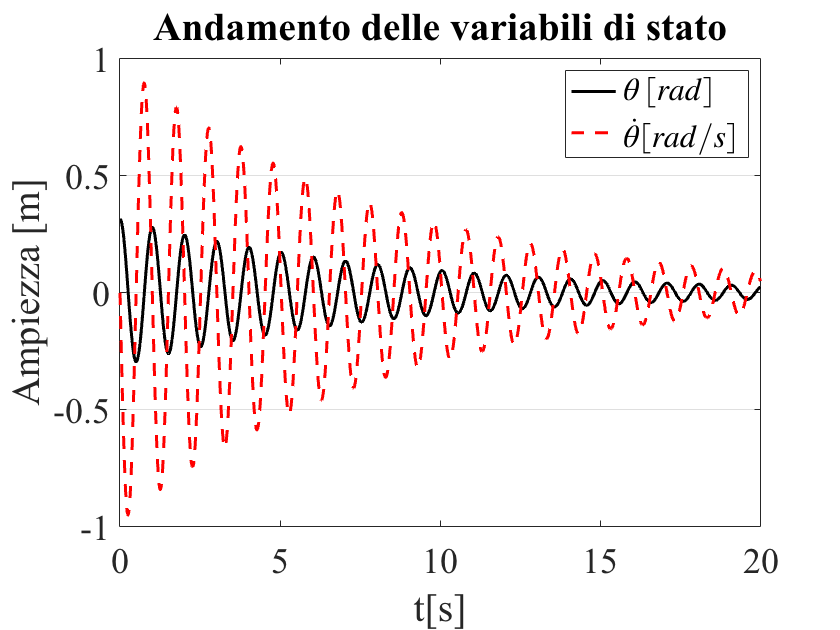

figure;
plot(t,x(:,1),'k-',t,x( :,2),'r--','LineWidth',2);
grid;
title ('Andamento delle variabili di stato','FontSize',25);
xlabel('t[s]','FontSize',14);
ylabel('Ampiezza [m]','FontSize',14)
legend('$\theta\,[rad]$','$\dot{\theta} [rad/s]$','Interpreter','latex');
ax = gca;
ax.XGrid = 'off';
ax.YGrid = 'on';
a = get(gca,'XTickLabel');
set(gca,'XTickLabel',a,'FontName','Times','fontsize',24);

Aggiorniamo ora le condizioni iniziali per vedere il risultato da un diverso stato iniziale:

x0_2 = [pi/10,2];
[t,x2]  = ode45(@(t,x)pendolo_smorzato(m,l,b,x,t),dt,x0_2,opts);
figure;
plot(t,x(:,1),'r--',t,x2(:,1),'k-','LineWidth',2);
legend ('$\theta_1\,[rad]$','$\theta_2 [rad]$','Interpreter','latex');
xlabel('t[s]','FontSize',14);
ylabel('Ampiezza [m]','FontSize',14)
ax = gca;
ax.XGrid = 'off';
ax.YGrid = 'on';
a = get(gca,'XTickLabel');
set(gca,'XTickLabel',a,'FontName','Times','fontsize',24);

Se invece di modificare la velocità iniziale modifichiamo l'angolo di partenza lasciando la velocità uguale a zero otteniamo:

x0_3 = [pi/3,0];
[t,x3]  = ode45(@(t,x)pendolo_smorzato(m,l,b,x,t),dt,x0_3,opts);
figure;
plot(t,x(:,1),'r--',t,x3(:,1),'k-','LineWidth',2);
legend ('$\theta_1\,[rad]$','$\theta_3 [rad]$','Interpreter','latex');
xlabel('t[s]','FontSize',14);
ylabel('Ampiezza [m]','FontSize',14)
ax = gca;
ax.XGrid = 'off';
ax.YGrid = 'on';
a = get(gca,'XTickLabel');
set(gca,'XTickLabel',a,'FontName','Times','fontsize',24);

### Studio Parametrico

Andiamo ora a modificare alcuni parametri impostati all'inizio dello studio per vedere come cambia la risposta del sistema. Studiamo prima l'andamento della posizione Theta:

layout = tiledlayout(3,1);

xlabel(layout,"t[s]",'FontSize',22);
ylabel(layout,"Ampiezza [m]",'FontSize',22);


l_aum = 10;%m
l_dim = 0.3; %m
[t,x_aum] = ode45(@(t,x)pendolo_smorzato(m,l_aum,b,x,t),dt,x0,opts);	
[t,x_dim] = ode45(@(t,x)pendolo_smorzato(m,l_dim,b,x,t),dt,x0,opts);
nexttile
plot(t,x_aum(:,1),'k-','LineWidth',2);%aumentata
hold on;
plot(t,x(:,1),'r:','LineWidth',3); %originale
plot(t,x_dim(:,1),'b-','LineWidth',2);%diminutia
title("L",'FontSize', 18);
ax = gca;
ax.FontSize = 18;


m_aum = 50;%kg
m_dim = 1;%kg
[t,x_aum] = ode45(@(t,x)pendolo_smorzato(m_aum,l,b,x,t),dt,x0,opts);
[t,x_dim] = ode45(@(t,x)pendolo_smorzato(m_dim,l,b,x,t),dt,x0,opts);
nexttile
plot(t,x_aum(:,1),'k-','LineWidth',2);%aumentata
hold on;
plot(t,x(:,1),'r:','LineWidth',3); %originale
plot(t,x_dim(:,1),'b-','LineWidth',2);%diminutia
title("m",'FontSize', 18);
ax = gca;
ax.FontSize = 18;

b_aum = 2;%kg/s
b_dim = 0.1; %kg/s
[t,x_aum] = ode45(@(t,x)pendolo_smorzato(m,l,b_aum,x,t),dt,x0,opts);
[t,x_dim] = ode45(@(t,x)pendolo_smorzato(m,l,b_dim,x,t),dt,x0,opts);
nexttile
plot(t,x_aum(:,1),'k-', 'LineWidth',2) %aumentata
hold on;
plot(t,x(:,1),'r:','LineWidth',3); %originale
plot(t,x_dim(:,1),'b-','LineWidth',2);%diminutia
title("b",'FontSize', 18);
ax = gca;
ax.FontSize = 18;

leg = legend( '$\theta_{aum}$','$\theta$','$\theta_{dim}$','Interpreter','latex','Orientation', 'Horizontal');
leg.Layout.Tile = 'north';
leg.FontSize= 30;

Studiamo ora invece l'andamento della velocità angolare Theta punto:

layout = tiledlayout(3,1);

xlabel(layout,"t[s]",'FontSize',22);
ylabel(layout,"Ampiezza [m]",'FontSize',22);


l_aum = 10;%m
l_dim = 0.3; %m
[t,x_aum] = ode45(@(t,x)pendolo_smorzato(m,l_aum,b,x,t),dt,x0,opts);	
[t,x_dim] = ode45(@(t,x)pendolo_smorzato(m,l_dim,b,x,t),dt,x0,opts);
nexttile
plot(t,x_aum(:,2),'k-','LineWidth',2);%aumentata
hold on;
plot(t,x(:,2),'r:','LineWidth',3); %originale
plot(t,x_dim(:,2),'b-','LineWidth',2);%diminutia
title("L",'FontSize', 18);
ax = gca;
ax.FontSize = 18;


m_aum = 50;%kg
m_dim = 1;%kg
[t,x_aum] = ode45(@(t,x)pendolo_smorzato(m_aum,l,b,x,t),dt,x0,opts);
[t,x_dim] = ode45(@(t,x)pendolo_smorzato(m_dim,l,b,x,t),dt,x0,opts);
nexttile
plot(t,x_aum(:,2),'k-','LineWidth',2);%aumentata
hold on;
plot(t,x(:,2),'r:','LineWidth',3); %originale
plot(t,x_dim(:,2),'b-','LineWidth',2);%diminutia
title("m",'FontSize', 18);
ax = gca;
ax.FontSize = 18;

b_aum = 2;%kg/s
b_dim = 0.1; %kg/s
[t,x_aum] = ode45(@(t,x)pendolo_smorzato(m,l,b_aum,x,t),dt,x0,opts);
[t,x_dim] = ode45(@(t,x)pendolo_smorzato(m,l,b_dim,x,t),dt,x0,opts);
nexttile
plot(t,x_aum(:,2),'k-', 'LineWidth',2) %aumentata
hold on;
plot(t,x(:,2),'r:','LineWidth',3); %originale
plot(t,x_dim(:,2),'b-','LineWidth',2);%diminutia
title("b",'FontSize', 18);
ax = gca;
ax.FontSize = 18;

leg = legend( '$\dot{\theta}_{aum}$','$\dot{\theta}$','$\dot{\theta}_{dim}$','Interpreter','latex','Orientation', 'Horizontal');
leg.Layout.Tile = 'north';
leg.FontSize= 30;

###  Flusso e spazio delle fasi

Andiamo ora a studiare lo spazio delle fasi, ciè il grafico che ha per assi tehta e theta punto.


[X,Y] = meshgrid(-0.4:0.05:0.4,-1.5:0.2:1.5);
dXdt = Y;
dYdt = -(b/(m*(l)^2))*Y-g/l*sin(X);
figure;
quiver(X,Y,dXdt,dYdt,1,'LineWidth',2);
grid;
title('Spazio delle fasi','FontSize',25);
xlabel('$\theta$[rad]','Interpreter','latex','FontSize',25);
ylabel('$\dot{\theta}[rad/s]$','Interpreter','latex','FontSize',25);

Se ci aggiungiamo sopra la traiettoria compiuta dal nostro sistema:

dt_f = [0:0.05:100]; %#ok<NBRAK> 
[t,x_f] = ode45(@(t,x)pendolo_smorzato(m,l,b,x,t),dt_f,x0,opts);
quiver(X,Y,dXdt,dYdt,1,'LineWidth',2);
hold on;
plot(x_f(:,1),x_f(:,2),'r-','LineWidth',1.2);
xlabel('$\theta$[rad]','Interpreter','latex','FontSize',25);
ylabel('$\dot{\theta}[rad/s]$','Interpreter','latex','FontSize',25);
grid on;

### Studio delle condizioni iniziali

Da ora in avanti si lavorerà con un pendolo che non è più smorzato, andiamo a ricavare l'equazione del modo.

Avremo bisogno di una nuova function, che si chiamerà "pendolo lineare" senza il termine di smorzamento, utilizzeremo gli stessi parametri iniziali, andiamo a integrare il pendolo:

opts = odeset('RelTol',1e-2,'AbsTol',1e-2);
[t,x_lin] = ode45(@(t,x)pendolo_lineare(t,x,m,l),dt,x0,opts);	

Andiamo ora a graficare le coordinate x(t) e y(t):

cord_x_lin = sin(x_lin(:,1))*l;
cord_y_lin = -cos(x_lin(:,1))*l;
figure;
plot(cord_x_lin,cord_y_lin);
xlabel('x(t)','FontSize',24);
ylabel('y(t)','FontSize',24);
grid on;
axis square;

Modificando le condizioni iniziali per ottenere una circonferenza compelta, metà circonferenza e infine un quarto:


l2 = tiledlayout(1,3);
xlabel(l2, "x(t)",'FontSize',18);
ylabel(l2, "y(t)",'FontSize',18);
title(l2, "Studio delle condizioni iniziali", 'FontSize', 30);
dt = [0:0.001:80]; %#ok<NBRAK> 

nexttile
x0_lin = [pi,0];

[t,x_lin] = ode45(@(t,x)pendolo_lineare(t,x,m,l),dt,x0_lin,opts);
cord_x_lin = sin(x_lin(:,1))*l;
cord_y_lin = -cos(x_lin(:,1))*l;
plot(cord_x_lin,cord_y_lin);
axis equal;
grid on;
xlim([-1 1]);
ylim([-1 1]);

nexttile
dt = [0:0.01:3]; %per evitare drift numerico si accorcia il tempo di simulazione in modo da avere una semicriconferenza che passi per 0
x0_lin = [pi/2,0];
[t,x_lin] = ode45(@(t,x)pendolo_lineare(t,x,m,l),dt,x0_lin,opts);
cord_x_lin = sin(x_lin(:,1))*l;
cord_y_lin = -cos(x_lin(:,1))*l;
plot(cord_x_lin,cord_y_lin);
axis equal;
grid on;
xlim([-1 1]);
ylim([-1 1]);

nexttile
x0_lin = [pi/4,0];
[t,x_lin] = ode45(@(t,x)pendolo_lineare(t,x,m,l),dt,x0_lin,opts);
cord_x_lin = sin(x_lin(:,1))*l;
cord_y_lin = -cos(x_lin(:,1))*l;
plot(cord_x_lin,cord_y_lin);
grid on;
axis equal;
xlim([-1 1]);
ylim([-1 1]);